# **Inverted pendulum using LQR**

## Objective:

The objective is to design and implement a control system that will Swing up & Balance the Pendulum in the vertical upward position using Linear Quadratic Regulator (LQR)

#### Let us look first at the parameters of the pendulum (Table 1):

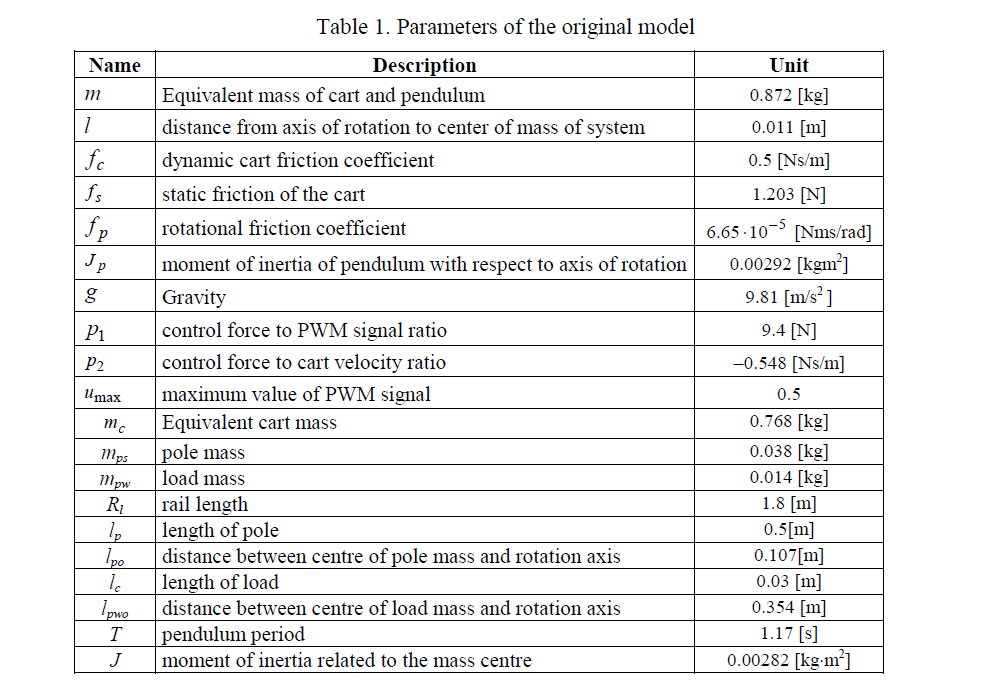

clear; clc; close all;

%% 1. System Parameters
% Parameters taken from Table 1 of the Manual
p.m  = 0.872;       % Equivalent mass of cart and pendulum [kg]
p.l  = 0.011;       % Distance from axis to center of mass [m]
p.g  = 9.81;        % Gravity [m/s^2]
p.fc = 0.5;         % Dynamic cart friction coefficient [Ns/m]
p.fp = 6.65e-5;     % Rotational friction coefficient [Nms/rad]
p.Jp = 0.00292;     % Moment of inertia of pendulum [kg*m^2]
p.p1 = 9.4;         % Control force to PWM signal ratio [N]
p.p2 = -0.548;      % Control force to cart velocity ratio [Ns/m]
p.u_max = 0.5;      % Max control signal magnitude 
p.fs = 1.203;       % Static Friction [N] 
p.Rl = 1.8;         % Rail length [m]

#### Now we check the dynamics of the pendulum:

Before that, let us define the state vector x:


$$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack ,\textrm{unde}\;\left\lbrace \begin{array}{l}
x_1 \;\textrm{is}\;\textrm{the}\;\textrm{position}\;\textrm{of}\;\textrm{hte}\;\textrm{cart}\\
x_2 \;\textrm{angle}\;\textrm{of}\;\textrm{the}\;\textrm{pendulum}\;\left(\textrm{consider}\;\textrm{that}\;0\;\textrm{is}\;\textrm{up}\right)\\
x_3 =\dot{x_1 } ,{\textrm{cart}}^{\prime } s\;\textrm{velocity}\\
x_4 =\dot{x_2 } ,\textrm{angular}\;\textrm{velocity}\;\left({\textrm{pendulum}}^{\prime } s\;\textrm{velocity}\right)
\end{array}\right.$$


With this information, now we will se the dynamics of the penudulum:

$\dot{x} =\left\lbrack \begin{array}{c}
\dot{x_1 } =x_3 \\
\dot{x_2 } =x_4 \\
\dot{x_3 } =\frac{a_1 w_1 \left(x,u\right)/+w_2 \left(x\right){\textrm{cosx}}_2 }{d\left(x\right)}\\
\dot{x_4 } =\frac{w_1 \left(x,y\right){\textrm{cosx}}_2 +a_2 w_2 \left(x\right)}{d\left(x\right)}
\end{array}\right\rbrack$,

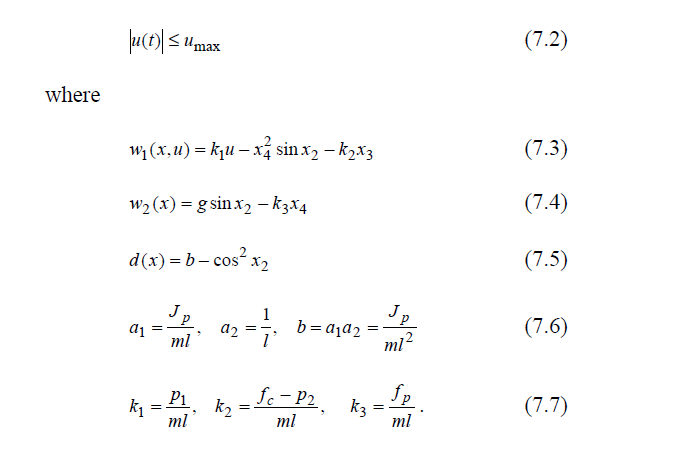

%% 2. Coefficients for Equations of Motion
p.a1 = p.Jp / (p.m * p.l);
p.a2 = 1 / p.l;
p.b  = p.Jp / (p.m * p.l^2);
p.k1 = p.p1 / (p.m * p.l);
p.k2 = (p.fc - p.p2) / (p.m * p.l);
p.k3 = p.fp / p.m;

## **The Prerequisite: Linearization**

Before applying LQR, we must satisfy the "L" in its name: **Linear**. Since real-world systems (like inverted pendulums) are non-linear, we must approximate the system dynamics.

We linearize the system around a specific equilibrium point (usually the upright position). This linear approximation is valid only within a small operating region—in our case, the interval [-0.3, 0.3] radians, approximately ( -17.1, 17.1). Outside this zone, the linear model fails, and the controller may become unstable.

## 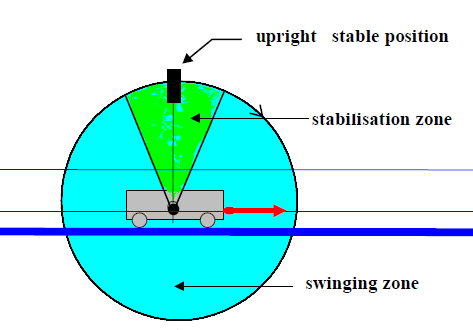

## What is LQR?

**LQR (Linear Quadratic Regulator)** is an optimal control strategy. While controllers like **PID (Proportional Integral Derivative)** rely on tuning gains based on error and heuristic behavior, and **MPC** (Model Predictive Control) optimizes over a receding horizon, LQR solves for a static gain that provides the best performance over an infinite horizon based on a mathematical model.

## **Mathematical Definition**

LQR calculates a state-feedback control law u = -Kx that minimizes a specific **quadratic cost function**. This function represents a "cost" accumulation over time, balancing the desire for zero error against the cost of using energy (control effort). 

### The cost function J is:

 $J=\int_0^{\infty } \left(x^T \textrm{Qx}+u^T \textrm{Ru}\right)\textrm{dt}$ for continuous-time systems 

OR

 $J=\sum_{k=0}^{\infty } \left(x{\left\lbrack k\right\rbrack }^T \textrm{Qx}\left\lbrack k\right\rbrack +u{\left\lbrack k\right\rbrack }^T \textrm{Ru}\left\lbrack k\right\rbrack \right)$ for discrete-time systems

## **Understanding Q and R**

The behavior of the controller is determined entirely by the tuning of the penalization matrices, **Q** and **R**. In practice, these are usually diagonal matrices.

### The Q Matrix (State Penalty):

- **Math:** Q must be a **positive semi-definite** matrix$\left(Q\succeq 0\right)$.

- **Function:** It penalizes the state vector $x$. Large values in Q tell the controller: *"It is very expensive to have a non-zero error in this state."* This forces the system to converge to equilibrium faster, potentially acting more aggressively.

### The R Matrix (Control Effort Penalty):

- **Math:** R must be a **positive definite** matrix$\left(R\succ 0\right)$.

- **Function:** It penalizes the control input u. Large values in R tell the controller: *"Using energy (voltage/fuel/force) is expensive."* This results in smoother, more conservative control actions to save energy

## **The Algebraic Riccati Equation (ARE)**

You have the system model (A, B) and the penalties (Q, R). You know you want to minimize the cost function J. The missing link is: **How do we actually find the optimal gain matrix ****K****?**

We cannot solve for K directly. Instead, we must first solve for an intermediate matrix, usually denoted as **P** (or sometimes S), using the **Algebraic Riccati Equation**.

### **The Continuous-Time Riccati Equation (CARE)**

For a continuous system, finding the optimal control requires solving the following non-linear matrix equation:


$$A^T P+\textrm{PA}-{\textrm{PBR}}^{-1} B^T P+Q=0$$


**Key details:**

- **The Unknown**: The matrix P. This is what we are solving for.

- **The Knowns**: A, B, Q, R.

- **Properties**: The solution P must be a symmetric, positive-definite matrix.

### **Calculating the Gain K**

Once we solve the Riccati equation and find the matrix P, the optimal feedback gain K is calculated using a simple formula:


$$K=R^{-1} B^T P$$


This K guarantees that the resulting closed-loop system (A-BK) is stable and the cost function J is minimized

### **The Discrete-Time Version (DARE)**

If you are implementing this on a microcontroller (which is discrete by nature), you are likely using the **Discrete Algebraic Riccati Equation**:


$$P=A^T \textrm{PA}-\left(A^T \textrm{PB}\right){\left(R+B^T \textrm{PB}\right)}^{-1} \left(B^T \textrm{PA}\right)+Q=0$$


The optimal feedback gain K is calculated using the formula


$$K={\left(R+B^T \textrm{PB}\right)}^{-1} \left(B^T \textrm{PA}\right)$$


Knowing this, let us liniarize the state vector x. We will use theese approximations:

$\left\lbrace \begin{array}{l}
\sin \left(x_2 \right)\approx x_2 \\
\cos \left(x_2 \right)\approx 1
\end{array}\right.$. It will become:


$$x=\left\lbrack \begin{array}{c}
x_3 =\dot{x_1 } \\
x_4 =\dot{x_2 } \\
\dot{x_3 } =\frac{a_1 \left(k_1 *u-x_4^2 *x_2 -k_2 *x_3 \right)+\left(g*x_2 -k_3 *x_4 \right)}{b-1}\\
\dot{x_4 } =\frac{\left(k_1 *u-x_4^2 *x_2 -k_2 *x_3 \right)+a_2 \left(g*x_2 -k_3 *x_4 \right)}{b-1}
\end{array}\right\rbrack$$


Now we extract the A and B state-space matrices $\left\lbrace \begin{array}{l}
A\in {\mathbb{R}}^{n\;x\;n} \\
B\in {\mathbb{R}}^{n\;x\;m} 
\end{array}\right.$:

Notation: $\textrm{denom}=b-1$


$$\left\lbrace \begin{array}{l}
A=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & \frac{g}{\textrm{denom}} & \frac{-a_1 *k_2 }{\textrm{denom}} & \frac{-k_3 }{\textrm{denom}}\\
0 & \frac{a_2 *g}{\textrm{denom}} & \frac{-k_2 }{\textrm{denom}} & \frac{-a_2 *k_3 }{\textrm{denom}}
\end{array}\right\rbrack \\
B=\left\lbrack \begin{array}{c}
0\\
0\\
\frac{a_1 *k_1 }{\textrm{denom}}\\
\frac{k_1 }{\textrm{denom}}
\end{array}\right\rbrack 
\end{array}\right.$$


Before doing anything else, we must ensure that our system is controllable. How do we do this? By calculating the controllability matrix 


$$C=\left\lbrack \begin{array}{ccccc}
B & \textrm{AB} & A^2 B & \ldots & A^{n-1} B
\end{array}\right\rbrack$$


and checking that its rank is n

%% 3. Linearization and LQR Design
% Linearize around upright: x2 = 0
denom = p.b - 1;

% State Matrix A 
A = zeros(4,4);
A(1,3) = 1;
A(2,4) = 1;
A(3,2) = p.g / denom;
A(3,3) = (-p.a1 * p.k2) / denom;
A(3,4) = -p.k3 / denom;
A(4,2) = (p.a2 * p.g) / denom;
A(4,3) = -p.k2 / denom;
A(4,4) = (-p.a2 * p.k3) / denom;

% Input Matrix B 
B = zeros(4,1);
B(3,1) = (p.a1 * p.k1) / denom;
B(4,1) = p.k1 / denom;

C = ctrb(A,B);

disp('The controllable matrix C is:');

The controllable matrix C is:


disp(C);

   1.0e+03 *

         0    0.0112   -0.0139    0.0309
         0    0.0367   -0.0458    1.2854
    0.0112   -0.0139    0.0309   -0.0554
    0.0367   -0.0458    1.2854   -1.6588




if rank(C) < 4
    disp('The system is not controllable. Check the parameters');
else
    disp('The system is controllable. Good to go')
end

The system is controllable. Good to go



disp(eig(A))

         0
    5.7634
   -5.8108
   -1.1998




% LQR Weighting
Q = diag([10, 100, 1, 1]); 
R = 0.1; 
K = lqr(A, B, Q, R);
disp('LQR Gain K:');

LQR Gain K:


disp(K);

  -10.0000   46.2417  -10.2323    6.7251



## The LQR in action:

Now that we know the system is fully controllable, we can try to solve the problem

%% 4. Non-Linear Simulation (ODE45)
% Initial State: [x1, x2, x3, x4]
% Start with pendulum DOWN (pi)
x0 = [0; pi; 0; 0]; 

t_span = [0 15]; % 15 seconds simulation

options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);
[t, x] = ode45(@(t,x) pendulum_dynamics(t, x, K, p), t_span, x0, options);


%% 5. Reconstruct Control Input for Plotting
u_history = zeros(length(t), 1);

for i = 1:length(t)
    [u_val, ~] = compute_control(x(i,:)', K, p);
    u_history(i) = u_val;
end

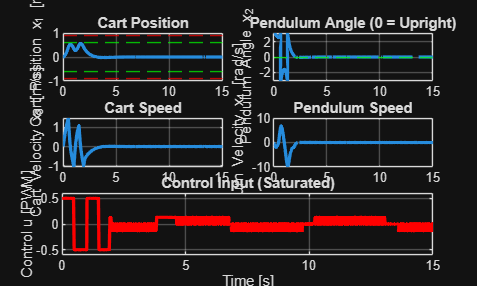

%% 6. Plotting Results (User Requested Layout)
figure;

subplot(3,2,1); plot(t, x(:,1), 'LineWidth', 2); grid on;
ylabel('Cart Position x_1 [m]'); title('Cart Position');
yline(p.Rl/2, 'r--'); yline(-p.Rl/2, 'r--');
yline(0.6, 'g--'); yline(-0.6, 'g--');

subplot(3,2,2); plot(t, wrapToPi(x(:,2)), 'LineWidth', 2); grid on;
ylabel('Pendulum Angle x_2 [rad]'); title('Pendulum Angle (0 = Upright)');
yline(0, 'g--'); 

subplot(3,2,3); plot(t, x(:,3), 'LineWidth', 2); grid on;
ylabel('Cart Velocity x_3 [m/s]'); title('Cart Speed');

subplot(3,2,4); plot(t, x(:,4), 'LineWidth', 2); grid on;
ylabel('Pendulum Velocity x_4 [rad/s]'); title('Pendulum Speed');

subplot(3,2,[5 6]); plot(t, u_history, 'r', 'LineWidth', 2); grid on;
ylabel('Control u [PWM]'); xlabel('Time [s]'); title('Control Input (Saturated)');
ylim([-0.6 0.6]);

## Obervations:

- You may notice that in the pendulum_dynamics, I have added a new member (f_static_term). It is used for simulating more accurately the real dynamics with frictions and everything

- There are some imaginary barriers that I have set. The reason is that the pendulum will not smash into the physical margins of the rail

- The first limiter is used in case the cart is dangerously close to the physical margins, and we forcefully stop the cart

- The second limiter is to keep the cart in the interval [-rail_safe_margin, rail_safe_margin]

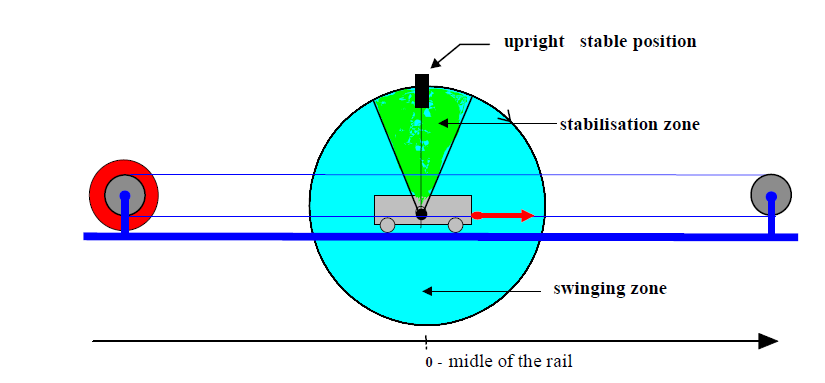

%% ---------------------------------------------------------
%  AUXILIARY FUNCTIONS
%  ---------------------------------------------------------

% 1. Dynamics Wrapper
function dxdt = pendulum_dynamics(~, x, K, p)
    % Unpack state
    x1 = x(1); x2 = x(2); x3 = x(3); x4 = x(4);

    % --- CONTROLLER ---
    [u, ~] = compute_control(x, K, p);

    % --- DYNAMICS ---
    % Static Friction opposing motion
    f_static_term = (p.fs / (p.m * p.l)) * sign(x3);
    
    % Equations of Motion
    w1 = p.k1 * u - (x4^2) * sin(x2) - p.k2 * x3 - f_static_term;
    w2 = p.g * sin(x2) - p.k3 * x4;
    
    d_x = p.b - (cos(x2))^2;
    
    dx1 = x3;
    dx2 = x4;
    dx3 = (p.a1 * w1 + w2 * cos(x2)) / d_x;
    dx4 = (w1 * cos(x2) + p.a2 * w2) / d_x;
    
    % Hard Rail Stop (Physics)
    if abs(x1) > 0.8
        dx1 = 0; dx3 = 0; 
    end
    
    dxdt = [dx1; dx2; dx3; dx4];
end

% 2. Hybrid Control Logic
function [u_out, mode] = compute_control(x, K, p)
    x1 = x(1); 
    x2 = wrapToPi(x(2)); 
    x3 = x(3); 
    x4 = x(4);
    
    % Constants
    angle_threshold = 0.3; % 17 degrees
    rail_safe_margin = 0.6; % Meters
    
    % --- MODE SELECTION ---
    if abs(x2) <= angle_threshold
        mode = 1; % LQR Stabilization
    else
        mode = 0; % Swing-Up
    end
    
    % --- CONTROL CALCULATION ---
    if mode == 1
        % LQR
        u_raw = -K * [x1; x2; x3; x4];
    else
        % Swing-Up: Energy Pumping
        % WE USE THE CORRECTED SIGN HERE
        % x4 * cos(x2) is negative when we want to push Right.
        % So we need u proportional to +1 when term is negative? 
        % No, we established that "Running Away" pumps energy.
        
        % At bottom: x2=pi, cos(x2)=-1.
        % If x4>0 (swing right), term = x4*cos = Negative.
        % We want u < 0 (Left).
        % So u = +1 * term? No, sign(-) = -1. 
        % So u = sign(term). 
        
        control_signal = sign(x4 * cos(x2)); 
        
        % Kick-start if stationary
        if abs(x4) < 0.01
            control_signal = 1;
        end
        
        u_raw = p.u_max * control_signal;
        
        % Soft Rail Safety (Override Swing-up if too close to edge)
        if x1 > rail_safe_margin
            u_raw = -p.u_max; % Force back to center
        elseif x1 < -rail_safe_margin
            u_raw = p.u_max;
        end
    end
    
    % --- FRICTION COMPENSATION ---
    u_comp = p.fs / p.p1;
    if abs(u_raw) > 0.001
        u_total = u_raw + sign(u_raw) * u_comp;
    else
        u_total = u_raw;
    end
    
    % --- SATURATION ---
    if u_total > p.u_max, u_total = p.u_max; end
    if u_total < -p.u_max, u_total = -p.u_max; end
    
    u_out = u_total;
end

# Bibliography:

- "Synthesis of a Predictive Control Law for a Nonlinear System", Vener Andrei

- "Model Control Systems 14th Edition", Richard C. Dorf and Robert H. Bishop

- "Data-Driven Science and Engineering"Steve L. Brunton and J. Nathan Kuts

- The model: "Pendulum-Cart System User's Manual", INTECO

- Professor Cristion Oara, Teoria Sistemelor Automate

- Professor Bogdan D. Ciubotaru, Control Optimal

- Proffesor Florin Stoican, Modelare si Simulare